# Exercise 4: Phased Array Antenna interference nulling over Terrain 

Applicable for both Radar and Communication applications

Number of steps: 6 

Expected completion time: 20 minutes

In this Exercise real life example of Intereference nulling using Phased array antenna is simulated.

Receive station and multiple transmit sites in a suburban environment is modeled. Antennas are situated to achieve line-of-sight visibility over intermediate terrain. Using Antenna Toolbox™ and Phased Array System Toolbox™ signal strength at the receiver site is assessed for main RF communication link in the presence of interference. Phased Array beamforming using MVDR algorith is performed to null the interference directions . 

clear
close all

## Create RF Scenario transmit and receive sites 

### Create RF receive site

Create a receive site in Goffstown, New Hampshire, US. Define the receive site to represent RF antenna (for RF comm link or radar). Show the site in Site Viewer and rotate the view to visualize the site with surrounding terrain.

%--------------------------
% ADD CODE HERE
% Hint: use rxsite object to create Receive site of Antenna Toolbox Site Viewer.
% Type 'doc rxsite' into the command line interface for more information. 
% Supply the "Name","Receive site", "Latitude" value 42.983723 and "Longitude" value -71.587173 as inputs.
% 
% Name the output object 'rx'.  


rx = rxsite("Name","Receive site", ...
    "Latitude",42.983723, ...
    "Longitude",-71.587173);
show(rx)                            % show Rx site using Site Viewer

### Create Tx Sites: 1 RFcommunication link and 2 interfering sites in 2.5 GHz Band

Create three transmit sites in the area and show the sites on the map. Each transmitter site represents a site for RF terminal. 

Transmit frequency is in S-band (2.5 GHz). 

St Anselm College site is main communication link with transmit power of 1 Watt. Bedford Town Center and Goffstown Police Dept sites are interfering sites with transmit power of 50 W. 

fq = 2.5e9; % 2.5 GHz
txBedford = txsite("Name","Interference 1", ...
    "Latitude",42.946193, ...
    "Longitude",-71.516234, ...
    "TransmitterPower",50, ...
    "TransmitterFrequency",fq);

txStA = txsite("Name","Tx Signal: St. Anselm College", ...
    "Latitude",42.987386, ...
    "Longitude",-71.507475, ...
    "TransmitterPower",1, ...
    "TransmitterFrequency",fq);

txGPD = txsite("Name","Interference 2", ...
    "Latitude",43.009335, ...
    "Longitude",-71.539083, ...
    "TransmitterPower",50, ...
    "TransmitterFrequency",fq);
txStA.AntennaHeight = 1;

txs = [txBedford, txStA, txGPD];
show(txs)
show(txStA,Icon='antenna.png')

## Verify Line-of-Sight Link Visibility

 A visible line-of-sight path is required for optimal propagation conditions. In the suburban environment considered here, terrain is the dominant obstacle to achieving line-of-sight visibility. Plot the line-of-sight propagation paths between the Receive station and transmit sites. The line-of-sight calculation includes terrain but no other obstacles and reveals obstructed line-of-sight with 1 of the three transmit sites.

% Place antennas on structures at receiver sites. Assume 6 m utility poles for Bedford
% and St. Anselm sites, and 15 m antenna pole at Goffstown Police Department.
txBedford.AntennaHeight = 6;
txStA.AntennaHeight = 6;
txGPD.AntennaHeight = 15;

% adjust height of antenna at Receive station until line-of-sight is achieved 
rx.AntennaHeight = 50;

% Display line-of-sight between tx and rx sites
for tx = txs
%--------------------------
% ADD CODE HERE
% Hint: use los object to display line-of-sight in Site Viewer.
% Type 'doc los' into the command line interface for more information. 
% Supply the tx and rx as inputs.
% 
% Name the output object 'rx'. 
%---------------------------
    los(tx,rx)
end


## Specify Receive and Transmit site antennas

### Import Receive Station Antenna Array (8x8 URA)

Import from URA created in Exercise 2 to generate a highly directive beam. Plot the radiation pattern on the map, using the default antenna orientation so that the antenna array is physically oriented in the east direction.

% import URA from Exercise 2 
load ex2_array.mat
rx.Antenna = ura8_8;

% Plot pattern on the map
%--------------------------
% ADD CODE HERE
% Hint: use pattern function to display antenna pattern in Site Viewer.
%  Type 'doc rxsite.pattern' into the command line interface for more information. 
% Supply the Rx site object (rx) and frequency (fq)
%---------------------------------

pattern(rx,fq)

### Create 4-by-4 Tx Site Antenna Array

For all transmitters we will use 4-by-4 rectangular array from a reflector-backed vertical dipole antenna element. At each transmit site, point the array toward the Receive station and plot the radiation pattern on the map.

txElement = reflectorDipoleElement(fq);

% Define array size
ntxrow = 4; ntxcol = 4;  
% Define element spacing
lambda = physconst("lightspeed")/fq;
drow = lambda/2;
dcol = lambda/2;
% Create antenna array
txarray = phased.URA("Size",[ntxrow ntxcol], ...
    "Element",txElement, ...
    "ElementSpacing",[drow dcol]);

% Assign array to each transmitter site and point toward Rx station
for tx = txs
    tx.Antenna = txarray;
    tx.AntennaAngle = angle(tx, rx);
    pattern(tx)
end

## Calculate Received Signal Strength From Signal link and interference without Beamforming

Use the free space propagation model to compute received signal strength from each Transmitter site. Received antenna is steered to Signal Transmitter (St Anselm) direction. (Assume a receiver sensitivity of -84 dBm)


steeringVector = phased.SteeringVector("SensorArray",rx.Antenna);

% Compute steering vector for receiver site antenna (steering to Transmit station (txs(2))
     [az,el] = angle(rx,txs(2));  % calculate steering direction angles from Rx to Tx
%--------------------------
% ADD CODE HERE
% Hint: use steeringVector object
%  Type 'doc steeringVector' into the command line interface for more information. 
% Supply the frequency (fq) and angle [az;el] values
% name output variable 'sv'
%---------------------------------
    sv = steeringVector(fq,[az;el]);
    
    % Update receive station radiation pattern
    rx.Antenna.Taper = conj(sv);
    pattern(rx,fq)

for tx = txs
    % Compute signal strength (dBm) using Longley-Rice for multiple transmitters
    ss = sigstrength(rx,tx,"longley-rice");
    disp("Signal strength from " + tx.Name + " Tx:")
    disp(ss + " dBm") 
end

Use Mouse keys to rotate Site Viewer image to visualize that interference direction coincide with some Receive antenna sidelobes. 

(Double click on a Receive site to select camera rotation origin)

## Interference Nulling Workflow using MVDR Beamformer

ura=rx.Antenna;
ura.Taper=1;

### Simulate the Received Signal

First, we define the incoming signal. The signal's baseband representation is a simple rectangular pulse as defined below:

t = 0:0.001:0.5;                % Time, sampling frequency is 1kHz
s = zeros(size(t));  
s = s(:);                       % Signal in column vector
s(201:210) = s(201:210) + 1;    % Define the pulse
%carrierFreq = 100e6;
lambda = physconst("lightspeed")/fq;

figure
set(gcf,'Visible','on')
plot(t,s)
title('Transmit Pulse')
xlabel('Time (s)')
ylabel('Amplitude (V)')

Use the collectPlaneWave method of the array object to simulate the received signal at the array. Signal arrives at the array from azd, eld degrees in azimuth and elevation; the received signal can be modeled a

% direction of signal (communication) beam
tx=txs(2);
  [azd,eld] = angle(rx,tx); 

inputAngle = [azd; eld];       
x = collectPlaneWave(ura,s,inputAngle,fq); % signal

figure
set(gcf,'Visible','on')
subplot(211)
plot(t,abs(x(:,1)))
axis tight
title('Pulse at Antenna El#1')
xlabel('Time (s)')
ylabel('Magnitude (V)')
subplot(212)
plot(t,abs(x(:,32)))
axis tight
title('Pulse at Antenna El#32')
xlabel('Time (s)')
ylabel('Magnitude (V)')

### Add Noise to Received signal

For realistic scenario include some thermal noise to the received signal. The noise can be modeled as complex, Gaussian distributed random numbers. In this exercise, we assume that the noise power is 0.5 watts, which corresponds to a 3 dB signal-to-noise ratio (SNR) at each antenna element.

% Create and reset a local random number generator so the result is the
% same every time.
rs = RandStream.create('mt19937ar','Seed',2008);
noisePwr = .01;   % noise power 
noise = sqrt(noisePwr/2)*(randn(rs,size(x))+1i*randn(rs,size(x)));

The total return is the received signal plus the thermal noise.

### **Add interference signals**

Model two interference signals arriving along the directions azimuth (azn) and elevation (eln) (degrees).

nSamp = length(t);
s1 = 10*randn(rs,nSamp,1);      % intereference 1
s2 = 10*randn(rs,nSamp,1);      % intereference 2

% direction of interference sites
txi=[txs(1) txs(3)];
  [azn,eln] = angle(rx,txi);
% received interference 
interference = collectPlaneWave(ura,[s1 s2],[azn'; eln'],fq);

rxInt = interference + noise;        % total interference + noise
rxSignal = x + rxInt;                % total received signal


The total return signal (rxSignal) has 64 columns, where each column corresponds to one antenna element. The plot below shows the magnitude plot of the signal for two channels (ch#1 and ch#32).

figure
set(gcf,'Visible','on')

subplot(211)
plot(t,abs(rxSignal(:,1)))
axis tight
title('Pulse at Antenna 1')
xlabel('Time (s)')
ylabel('Magnitude (V)')
subplot(212)
plot(t,abs(rxSignal(:,32)))
axis tight
title('Pulse at Antenna 32')
xlabel('Time (s)')
ylabel('Magnitude (V)')

### Create MVDR Beamformer object

Create an MVDR beamformer pointing to the target signal direction.

%--------------------------
% ADD CODE HERE
% Hint: use phased.MVDRBeamformer to create a narrowband minimum-variance distortionless-response beamformer 
%  Type 'doc phased.MVDRBeamformerr' into the command line interface for more information. 
% Supply the Direction (inputAngle) and 'OperatingFrequency' (fq) values,
% and set 'TrainingInputPort'and'WeightsOutputPort' values to 'true'
% Name the output object 'mvdrbeamformer'.
%---------------------------------

mvdrbeamformer = phased.MVDRBeamformer('SensorArray',ura,...
    'Direction',inputAngle,'OperatingFrequency',fq,...
    'TrainingInputPort',true,'WeightsOutputPort',true);

### Apply MVDR Beamformer

Finally, apply the MVDR beamformer to the received signal and plot its output.

%--------------------------
% ADD CODE HERE
% Supply the Received Signal (rxSignal) and Trainiing Data (rxInt) values,
% Name the output 'yURA' and 'w'.
%---------------------------------

[yURA,w]= mvdrbeamformer(rxSignal,rxInt); 

figure
set(gcf,'Visible','on')
plot(t,abs(yURA)); axis tight;
title('Output of MVDR Beamformer for URA');
xlabel('Time (s)');ylabel('Magnitude (V)');

### Plot Array Radiation pattern after beamforming

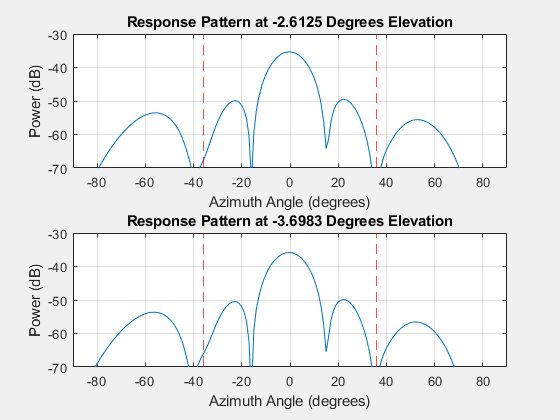

rx.Antenna.Taper =conj(sum(w,2));
figure
set(gcf,'Visible','on')
subplot(2,1,1);
pattern(ura,fq,-180:180,eln(1),'Weights',conj(w),'Type','powerdb',...
    'PropagationSpeed',physconst('LightSpeed'),'Normalize',false,...
    'CoordinateSystem','rectangular');
title("Response Pattern at " + eln(1) + " Degrees Elevation");
axis([-90 90 -70 -30]);
xline(azn,'--r')
subplot(2,1,2);
pattern(ura,fq,-180:180,eln(2),'Weights',conj(w),'Type','powerdb',...
    'PropagationSpeed',physconst('LightSpeed'),'Normalize',false,...
    'CoordinateSystem','rectangular');
axis([-90 90 -70 -30]);
title("Response Pattern at " + eln(2) + " Degrees Elevation");
xline(azn,'--r')

## Update Receive station antenna pattern and compute Signal Strength

% Update Receive station antenna pattern

rx.Antenna.Taper =conj(sum(w,2));
pattern(rx,fq)

% Compute signal strength (dBm) using Longley-Rice for multiple transmitters
for tx = txs
    ss = sigstrength(rx,tx,"longley-rice");
    disp("Signal strength from " + tx.Name + " Tx:")
    disp(ss + " dBm") 
end

Use Mouse keeys to rotate Site Viewer image to visualize that this time interference direction is between Receive antenna sidelobes.

## Bonus step: Simultaneous Transmission

Assuming that all 3 Tx sites are useful communication links, generate a Rx antenna pattern that can receive all Tx sites simultaneously. The single beam generates radiation lobes toward the three receiver sites. 

steeringVector = phased.SteeringVector("SensorArray",rx.Antenna);

% Compute steering vector for transmit site
[az,el] = angle(txs,rx);
sv = steeringVector(fq,[az el]);

% Update base station radiation pattern
rx.Antenna.Taper = conj(sum(sv,2));
pattern(rx,fq)

% Compute signal strength (dBm)
for tx = txs
    ss = sigstrength(rx,tx,"freespace");
    disp("Signal strength at " + tx.Name + ":")
    disp(ss + " dBm")
end

## Summary

This example shows how to integrate Phased Array antenna model in RF scenario. We used Antenna Toolbox Site and terrain visualization, propagation visualization capabilities to model RF link over terrain in a multi-user suburban scenario.

We demonstrated how to calculate received signal power taking into account antenna patern.

At the end demonstrated MVDR Beamformer workflow to model MVDR beamforming to suppress interference. 

function element = reflectorCrossedDipoleElement(fq, showAntenna)
%reflectorCrossedDipoleElement   Design reflector-backed crossed dipole antenna element

if nargin < 2
    showAntenna = false;
end

lambda = physconst("lightspeed")/fq;
offset = lambda/50;
gndspacing = lambda/4;
gndLength = lambda;
gndWidth = lambda;

% Design crossed dipole elements
d1 = design(dipole,fq);
d1.Tilt = [90,-45];
d1.TiltAxis = ["y","z"];
d2 = copy(d1);
d2.Tilt = 45;
d2.TiltAxis = "x";

% Design reflector
r = design(reflector,fq);
r.Exciter = d1;
r.GroundPlaneLength = gndLength;
r.GroundPlaneWidth = gndWidth;
r.Spacing = gndspacing;
r.Tilt = 90;
r.TiltAxis = "y";
if showAntenna
    show(r)
end

% Form the crossed dipole backed by reflector
refarray = conformalArray;
refarray.ElementPosition(1,:) = [gndspacing 0 0];
refarray.ElementPosition(2,:) = [gndspacing+offset 0 0];
refarray.Element = {r, d2};
refarray.Reference = "feed";
refarray.PhaseShift = [0 90];
if showAntenna
    show(refarray);
    view(65,20)
end

% Create custom antenna element from pattern
[g,az,el] = pattern(refarray,fq);
element = phased.CustomAntennaElement;
element.AzimuthAngles = az;
element.ElevationAngles = el;
element.MagnitudePattern = g;
element.PhasePattern = zeros(size(g));
end

function element = reflectorDipoleElement(fq)
%reflectorDipoleElement   Design reflector-backed dipole antenna element

% Design reflector and exciter, which is vertical dipole by default
element = design(reflector,fq);
element.Exciter = design(element.Exciter,fq);

% Tilt antenna element to radiate in xy-plane, with boresight along x-axis
element.Tilt = 90;
element.TiltAxis = "y";
element.Exciter.Tilt = 90;
element.Exciter.TiltAxis = "y";
end